# Heat Equation on a Square Plate

The basic heat equation is


$$\frac{\partial u}{\partial t} = k \Delta u$$


geomFileName = "pdeGeom_SQ1-C1_C2.mat";
if ~exist(geomFileName,'file')
    pderect([-1 1 -1 1])
    pdecirc(-0.5,-0.5,0.25)
    pdecirc(0.5,0.5,0.25)
    pdeModeler
    save(geomFileName,"gd","sf","ns")
else
    load(geomFileName,"gd","sf","ns")
end

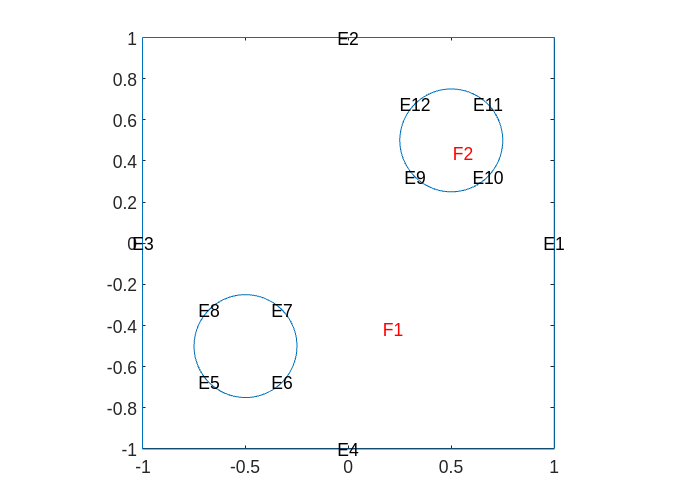

pdeGeom = decsg(gd,sf,ns);
pdegplot(pdeGeom,"EdgeLabels","on","FaceLabels","on")
axis equal

## PDE model

Create a PDE Model with a single dependent variable

numberOfPDE = 1;
pdeModel = createpde(numberOfPDE);
geometryFromEdges(pdeModel,pdeGeom);

## Problem Definition


$$m \frac{\partial^2 u}{\partial t^2} + d \frac{\partial u}{\partial t} - \nabla(c \nabla u) + a\, u = f$$


k = 0.025;

c = k;
a = 0;
f = 0;
d = 1;

specifyCoefficients(pdeModel,"m",0,...
                             "d",1,...
                             "c",1,...
                             "a",0,...
                             "f",0);

## Apply Boundary Conditions

% Solution is zero at all four outer edges of the square
% applyBoundaryCondition(pdeModel,'Edge',1:size(pdeGeom,2), 'u', 0);

applyBoundaryCondition(pdeModel,"neumann", ...
    "Edge",1:8, ...
    "g",0, ...
    "q",0);

## Generate Mesh

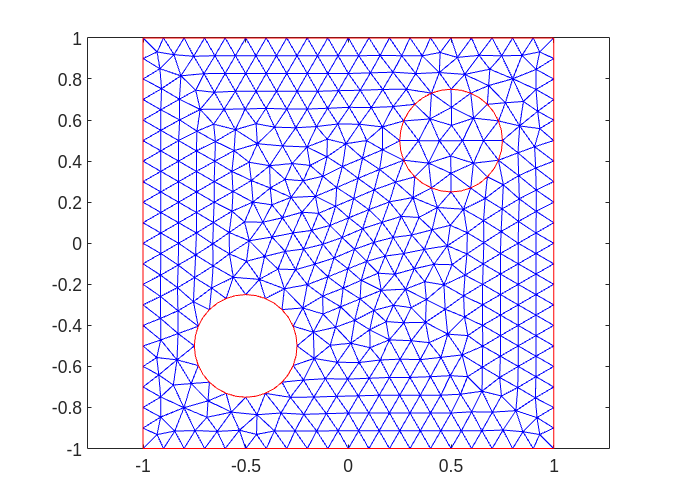

msh = generateMesh(pdeModel,'Hmax',0.1);
figure;
pdemesh(pdeModel);
axis equal

## Initial Conditions

setInitialConditions(pdeModel,0);
setInitialConditions(pdeModel,1,"Face",2);

tlist = logspace(-2,1,150);
results = solvepde(pdeModel,tlist);

sol = results.NodalSolution;

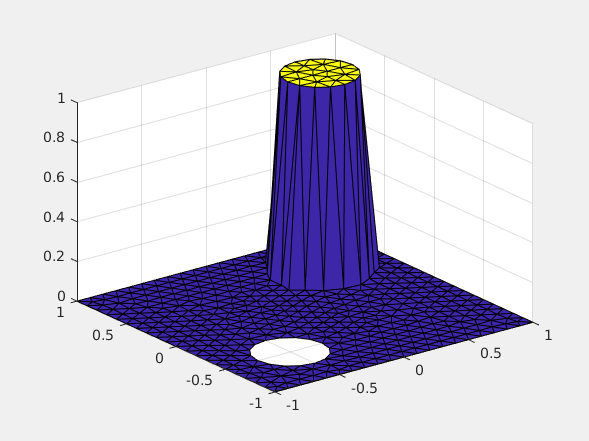

fig = figure(123);
fig.Visible = 'on';
delete(fig.Children);
ax = axes(fig);

Tri = msh.Elements(1:3,:)';
Sf = trisurf(Tri,msh.Nodes(1,:)',msh.Nodes(2,:)',sol(:,1));

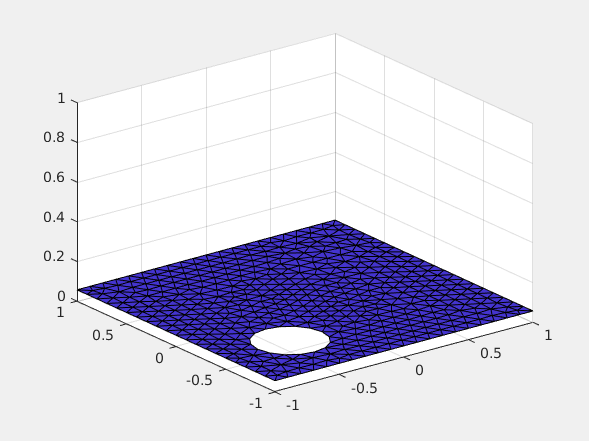


for i = 1:numel(tlist)
    Sf = trisurf(Tri,msh.Nodes(1,:)',msh.Nodes(2,:)',sol(:,i));
    zlim([0,1])
    clim([0,1])
    drawnow
end